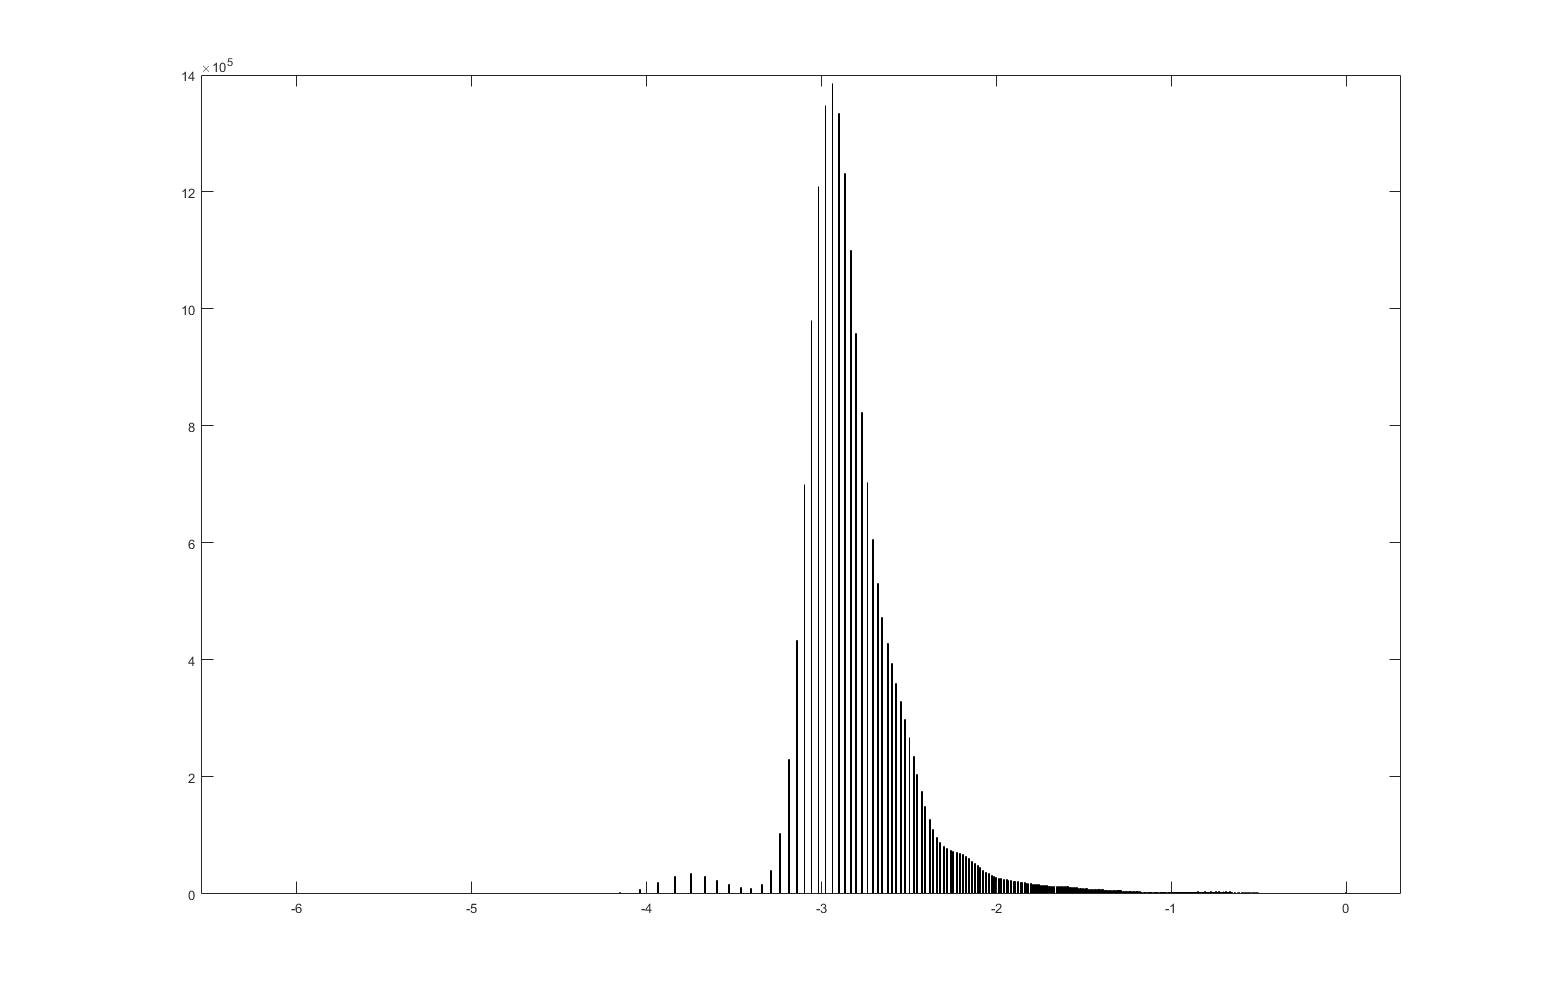

A = double(imread('_MG_7735.JPG'))/255;
B = double(imread('_MG_7737.JPG')) /255;

DIF = abs(A-B); % imatge diferencia
maxim = max(DIF(:));
DIF = DIF/maxim; % dividim pel seu valor màxim

Bd = imtranslate(B,[20, -20]);
DIF = abs(A-Bd);
maxim = max(DIF(:));
DIF = DIF/maxim;

Am = (A+Bd)/2; % imatge millorada

R = Am(:, :, 1);
G = Am(:, :, 2);
B = Am(:, :, 3);

RGB(:, :, 1) = R; RGB(: ,:, 2) = G; RGB(:, :, 3) = B;

R = log(R);
histogram(R);

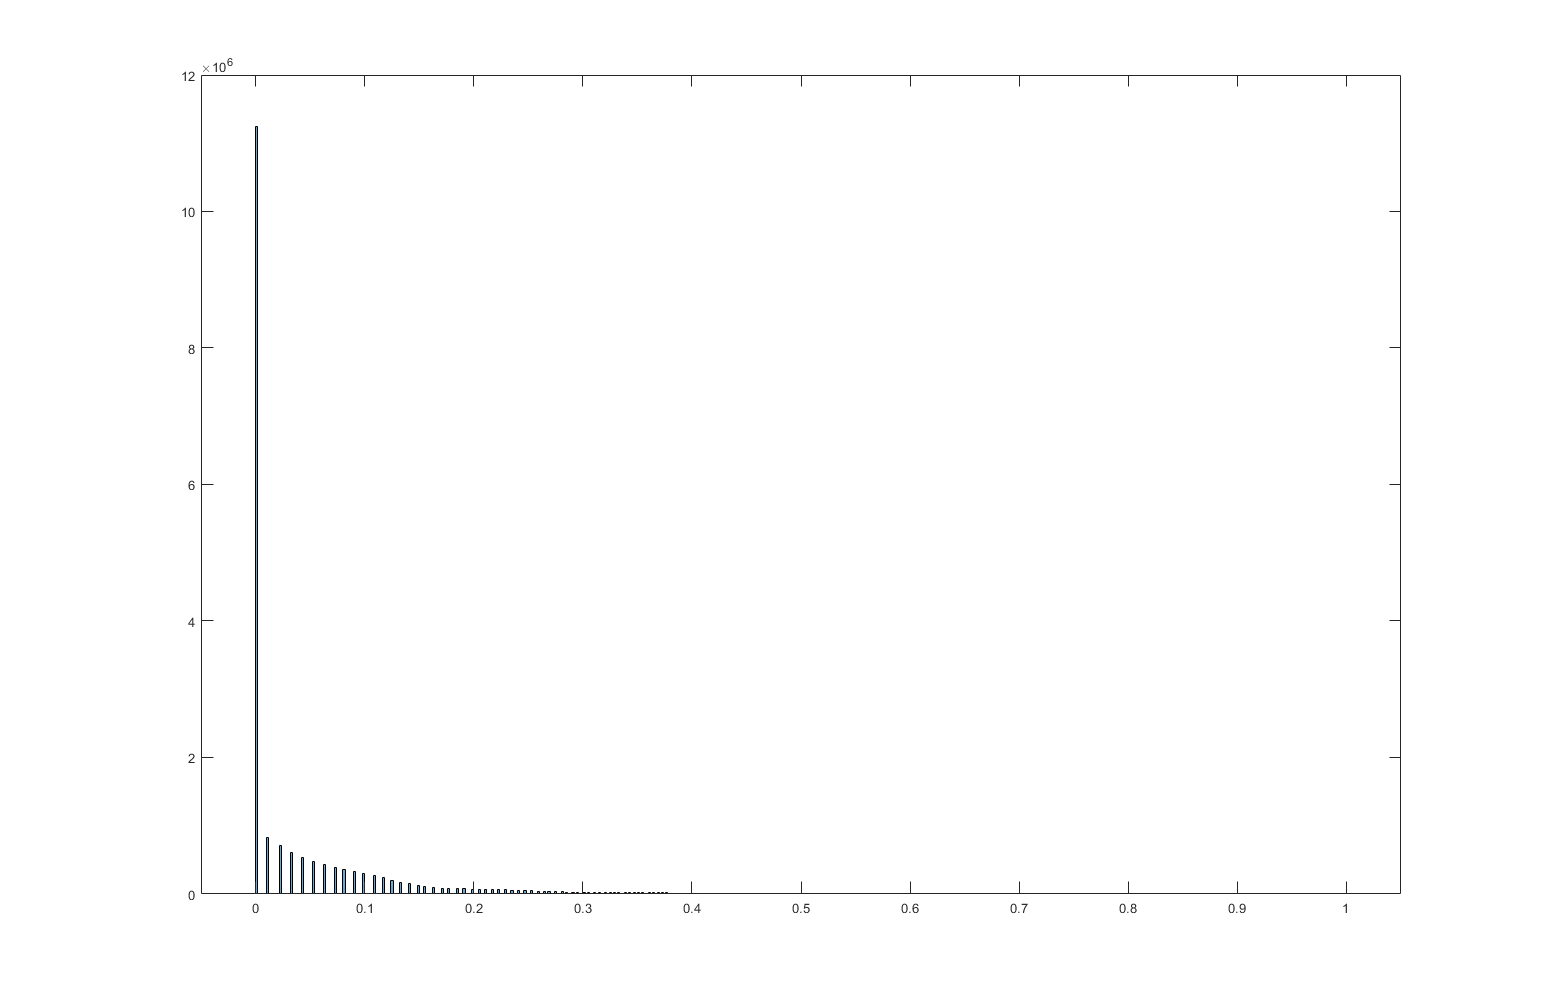


blacklevel = -2.8;
R = rescale(R, "InputMin", blacklevel);

histogram(R);

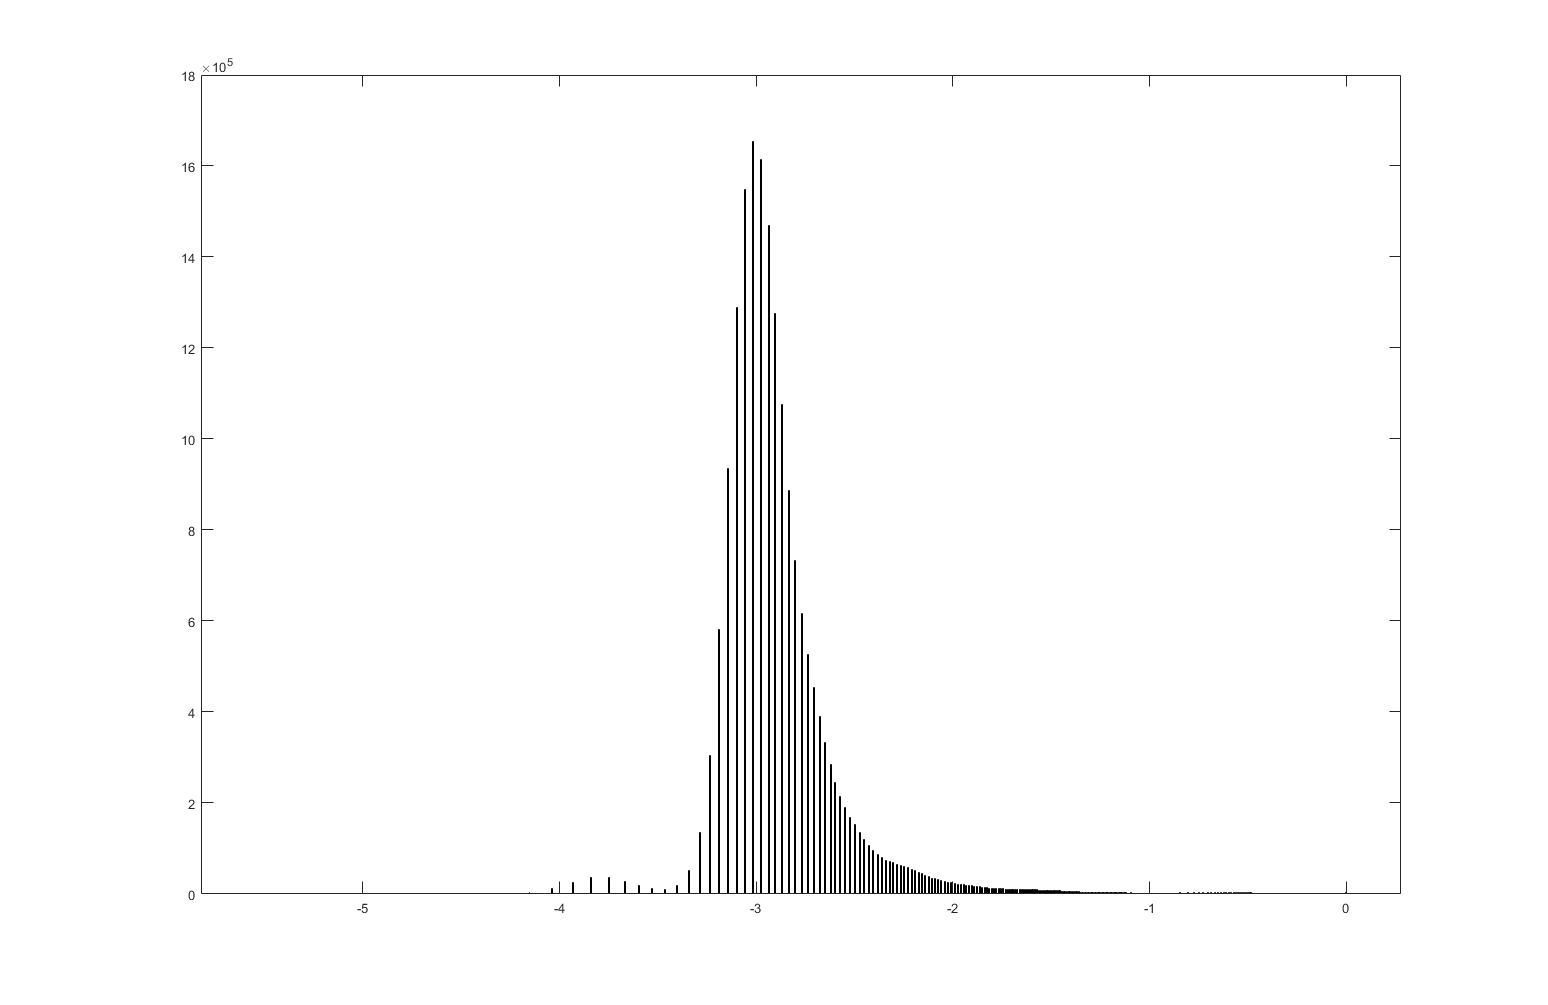

G = log(G);
histogram(G);

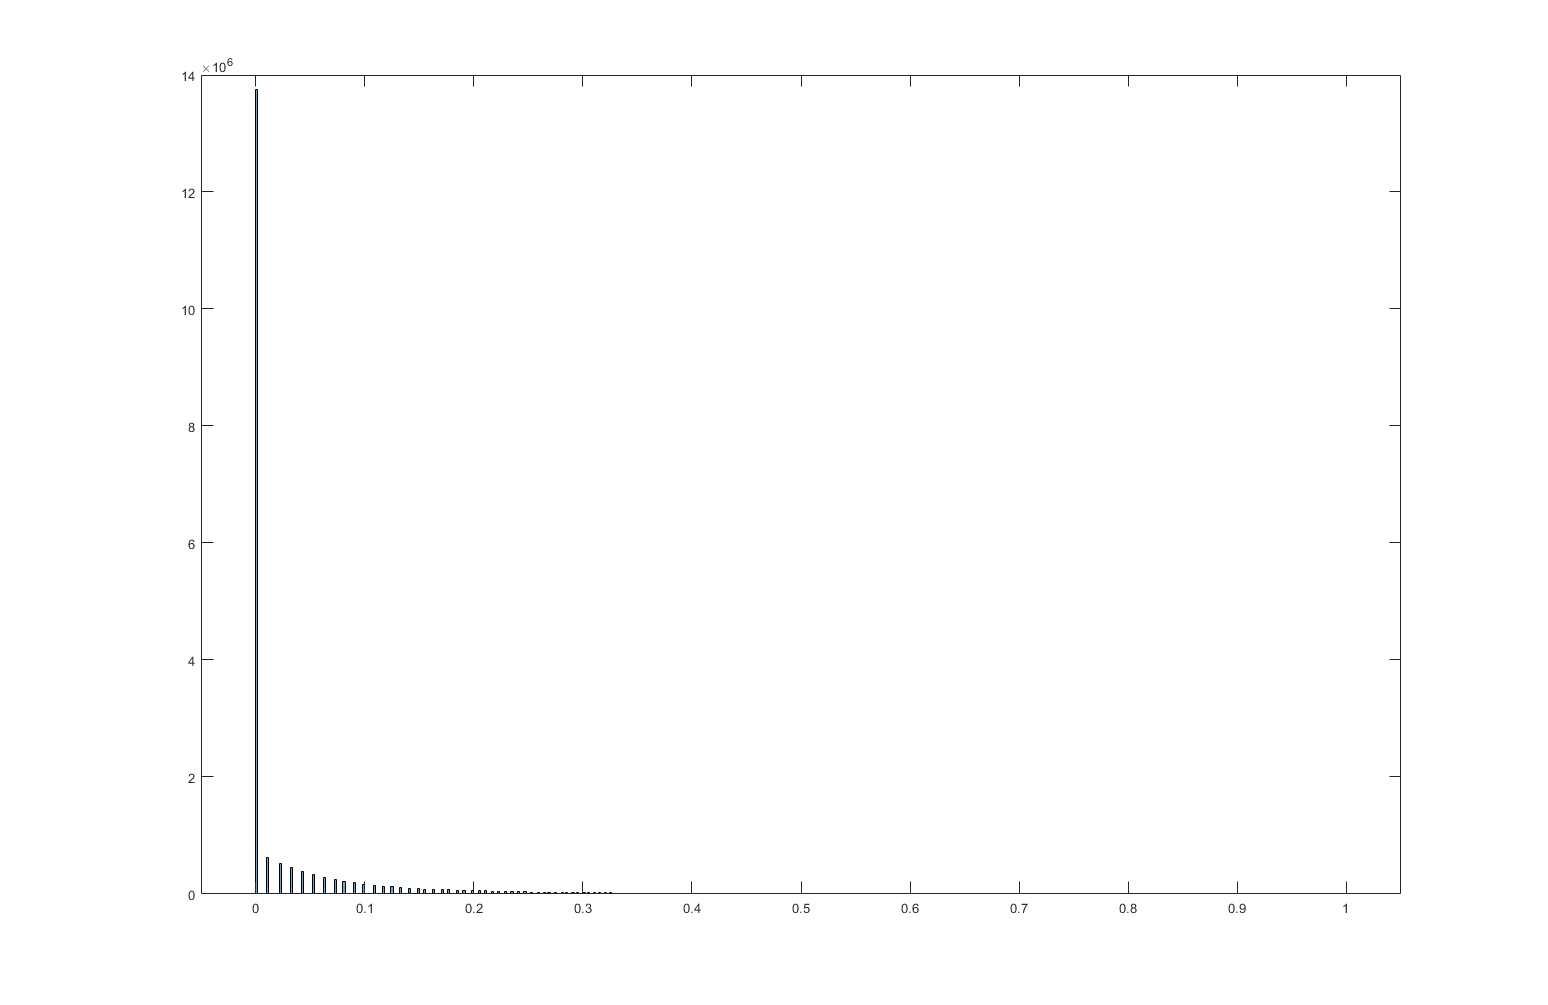


blacklevel = -3;
G = rescale(G, "InputMin", blacklevel);

histogram(G);

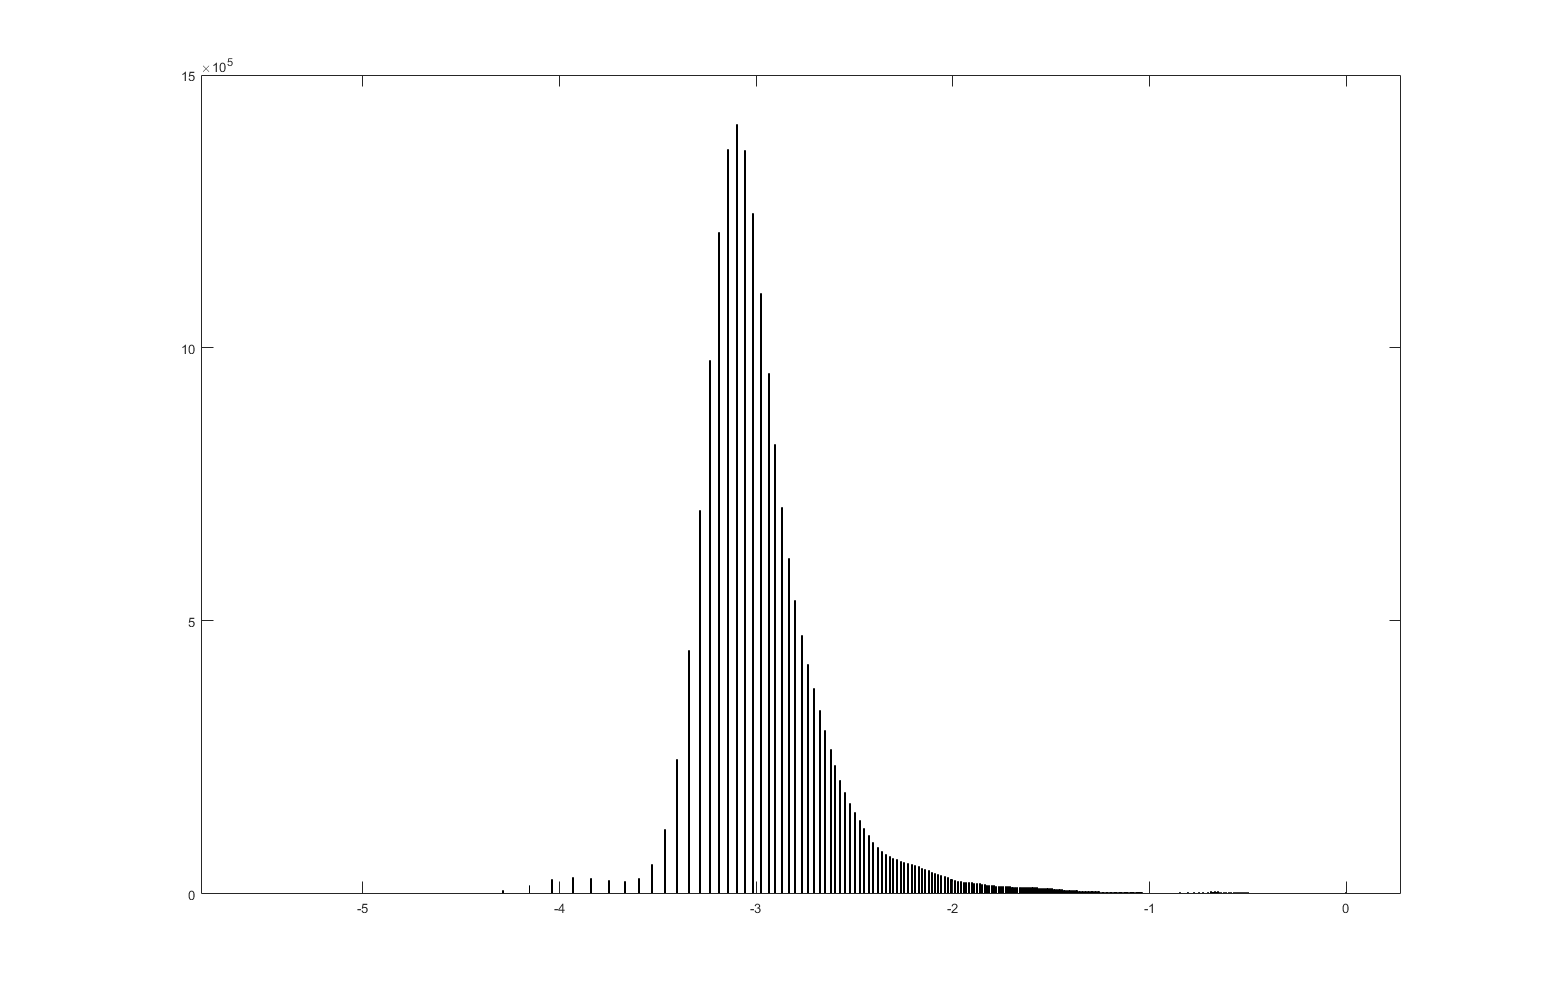


B = log(B);
histogram(B);

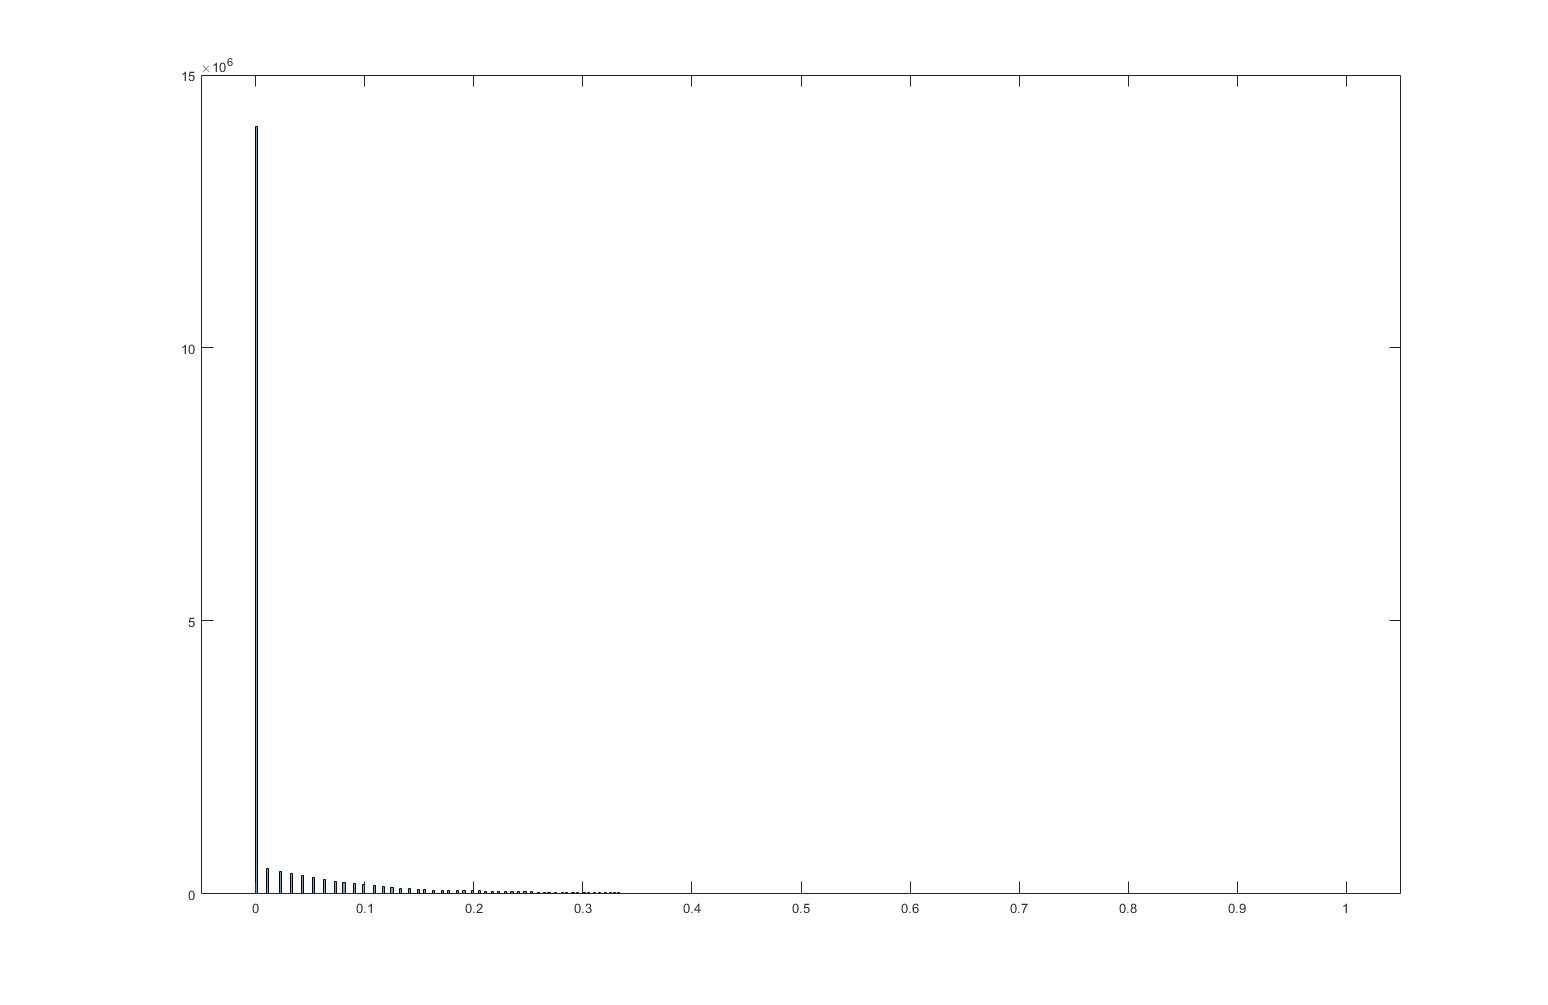


blacklevel = -3.2;
B = rescale(B, "InputMin", blacklevel);

histogram(B);

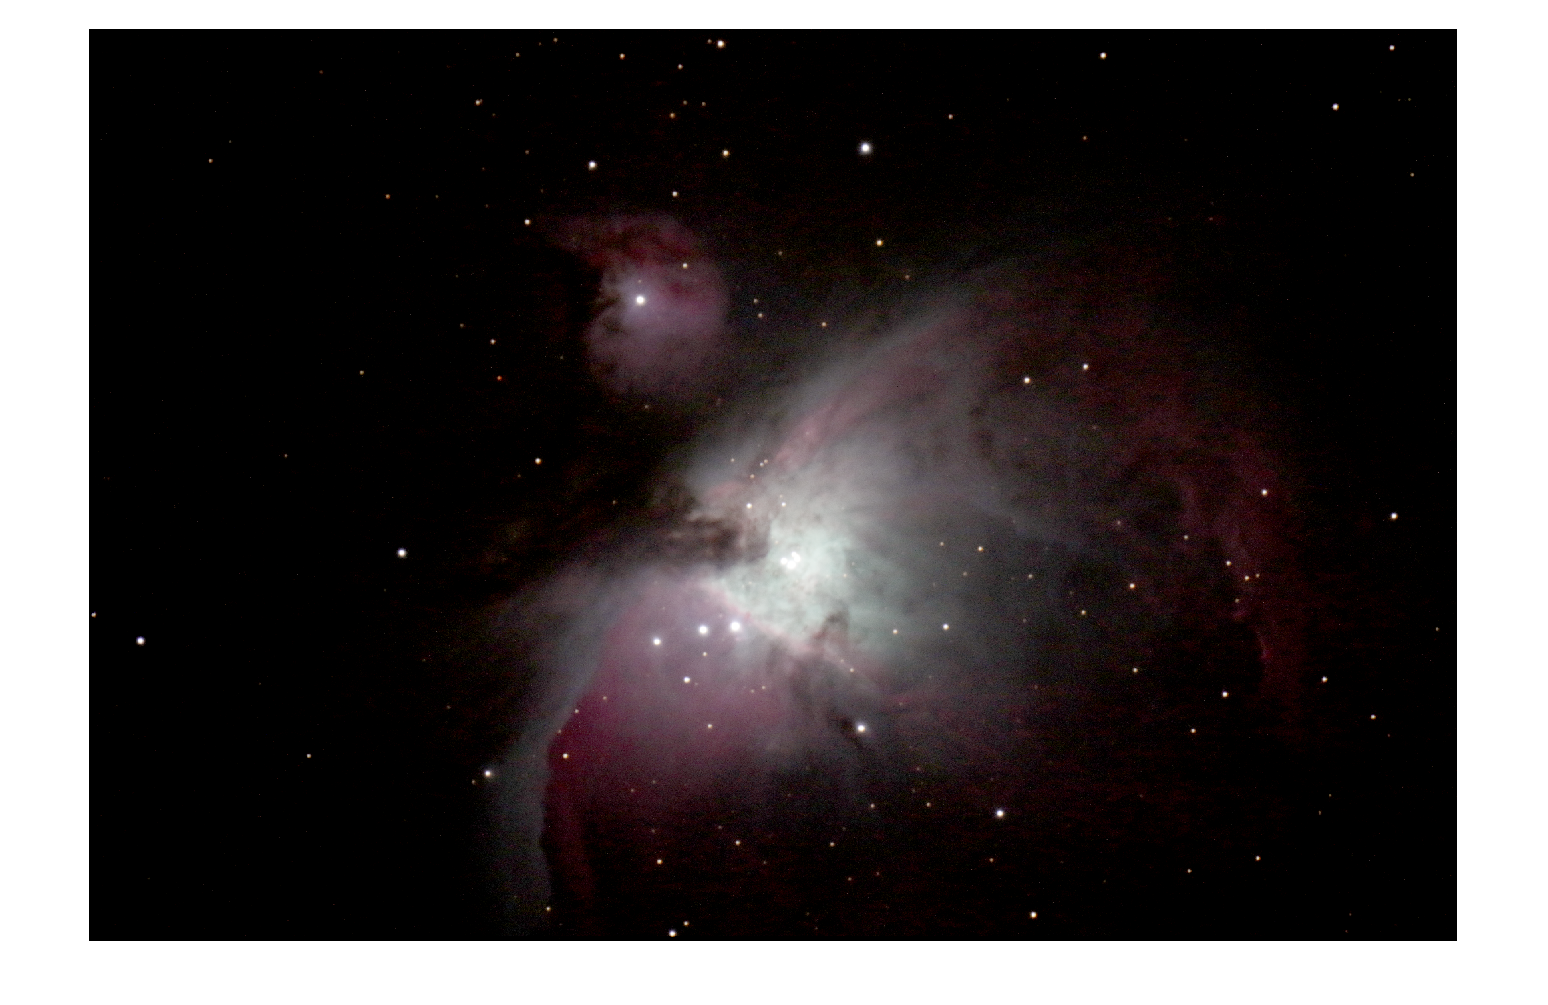

R = imadjust(adapthisteq(R, "Distribution", "exponential", "NumTiles", [2, 2]), [0.01, 1], [], 1);
B = imadjust(adapthisteq(B, "Distribution", "exponential", "NumTiles", [2, 2]), [0.01, 1], [], 1);
G = imadjust(adapthisteq(G, "Distribution", "exponential", "NumTiles", [2, 2]), [0.01, 1], [], 1);

img = cat(3, R, G, B);
imshow(img)